%Luis Mario Bres Castro
%Final Lab 1



P=struct('f0',150,'f1',4,'psi0',0);

% Data generation parameters
sampFreq = 1024;
timeVec = 0:1/sampFreq:1;

%Instantaneous phase
%I(t)=2*pi*f0*t
%dI/dt=f0
% maxFreq = f0;
A=1;
%Generate AM Signal
sigVec = AMSigGen_new(timeVec,A,P);
%%
nSamples=length(timeVec);
dataLen = timeVec(end)-timeVec(1);
kNyq = floor(nSamples/2)+1;
posFreq = (0:(kNyq-1))*(1/dataLen);



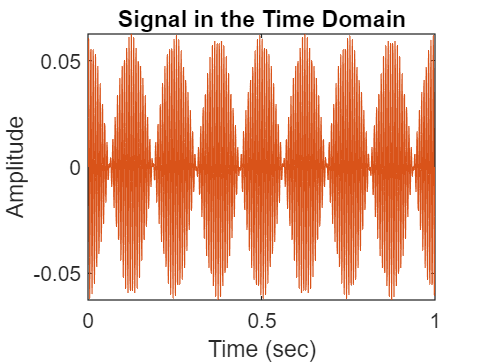

% Plot of signal
figure;
plot(timeVec,sigVec);
hold on;
plot(timeVec,sigVec);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Signal in the Time Domain')

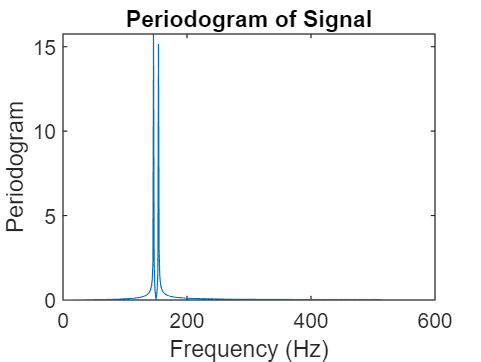

%Periodogram of the signal

fftsig=fft(sigVec); %FFT of signal
fftsig=fftsig(1:kNyq); %Only positive frequencies
%Plot of periodogram
figure
plot(posFreq, abs(fftsig));
title('Periodogram of Signal');
xlabel('Frequency (Hz)');
ylabel('Periodogram');